% same script (criteria) used for all treatments 

cd('path\BX') % raw data not uploaded, can be optained by contacting Johanna Pedersen 
p0 = imread('0.JPG'); 

light_org = imread('path\l1.JPG');

% 'YY' depends on the threshold, see details in supporting materials of the
% paper for the threshold value of each treatment 

p0bw = (p0(:, :, 1) > 'YY');

% need a mask due to the beaker with slurry
% imshow(p0)
% h = imfreehand
% mask = createMask(h);
% save mask

load('mask')

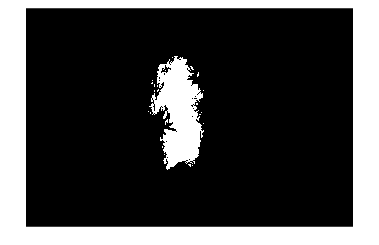

p0bw = p0bw.*mask; 

imshow(p0bw)


A0a = sum(p0bw(:));

test1_area = A0a .* slope

test1_area = 153.8409